# Mathieu Beam's in the Optical Tweezers Toolbox

This demonstration shows how to generate Mathieu beams using the optical tweezers toolbox and calculate the transverse force distributions.

This file was originally released as supplementary material to:

CITATION

If you find this file useful, please consider citing the paper.

## Setting up the parameters for a Mathieu beam

A Mathieu beam is created using the `ott.BscPmMathieu` beam class.  This class uses point-matching in the paraxial far-field to calculate the beam shape coefficients for a Mathieu beam.  The following parameters control the type of beam generated:

index_medium = 1  % Refractive index in medium

index_medium = 1

NA = 1           % Numerical aperture of lens

NA = 1

scale = 0.14   % Scale relative to objective aperture

scale = 0.1400


order = 3         % Mathieu beam order (m)

order = 3

parity = 'even'               % Mathieu beam parity (q)

parity = 'even'


ellipticity = 30% Mathieu beam helicity

ellipticity = 30

ifocal = 0.1      % Interfocal separation

ifocal = 0.1000

- The size of the focussed Mathieu beam is controlled the Numerical aperture of the objective, the refractive index of the medium and the `scale` factor.  A small scale factor creates a more paraxial beam while a large scale factor results in a significant portion of the light being clipped by the objective back aperture.

- `order` and `parity` control the type of Mathieu beam.

- `ellipticity and ifocal` control the shape of the Mathieu beam.  These parameters are related to the transverse spatial frequency $k_T$ by

                     
$$\textrm{ellipticity}=\frac{{\textrm{ifocal}}^{2\;} k_T^2 }{4}$$


Some combinations of parameters may not generate nice looking beams.  You may need to increase the `Nmax` used for the point-matching or change the resolution of the paraxial images (256x256 by default).  Increasing these will take longer but should improve acuracy.

Nmax = 30;
Nres = 256;

There may be other artifact from the objective aperture clipping the beam.  If a significant portion of the light is outside the objective aperture the resulting beam will not look like a Mathieu beam.

## Calculating the Mathieu beam

The `ott.BscPmMathieu` beam class can be used to calculate both the complex paraxial far-field and the beam shape coefficients.

To calculate the paraxial far-field use the `calculate_scalar_field` static function:

eScalar = BscPmMathieu.calculate_scalar_field(...
    parity, order, scale, ellipticity, ifocal, 'Nres', Nres, ...
    'projection', 'tanasin');

To calculate the beam shape coefficients for the focussed beam use the class constructor:

beam = BscPmMathieu(NA, order, parity, ...
    'ellipticity', ellipticity, 'scale', scale, ...
    'index_medium', index_medium, 'ifocal', ifocal, ...
    'Nres', Nres, 'Nmax', Nmax, 'projection', 'tanasin');

## Visualising the Mathieu beam

The following code creates visualisation of the paraxial beam in the far-field, the focussed beam in the far-field after clipping by the objective aperture, and the focussed beam in the near-field.

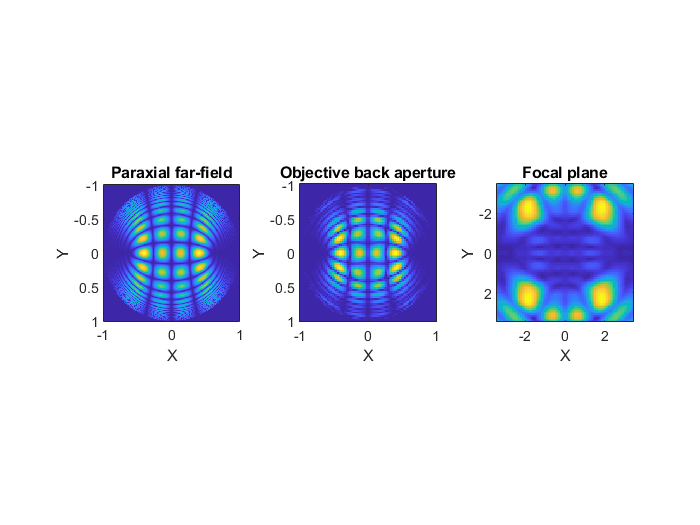

figure();
subplot(1, 3, 1);
x = linspace(-1, 1, size(eScalar, 1));    % For axis range
y = linspace(-1, 1, size(eScalar, 2));
imagesc(x, y, abs(eScalar));    % Plot the magnitude, could also look at the phase
axis image;
xlabel('X');
ylabel('Y');
title('Paraxial far-field');

subplot(1, 3, 2);
beam.basis = 'incoming';
beam.visualiseFarfield('dir', 'pos');
title('Objective back aperture');

subplot(1, 3, 3);
% Units depend on wavelength/frequency, but default should be
% in units of wavelength
beam.basis = 'regular';
beam.visualise();
title('Focal plane');

## Calculating force fields

The beam object can be used to calculate the optical forces fields acting on a particle.  For this we need to set-up a particle

sphere = ott.TmatrixMie(1.0, 'index_relative', 1.5);

Then we can calculate the forces at different locations

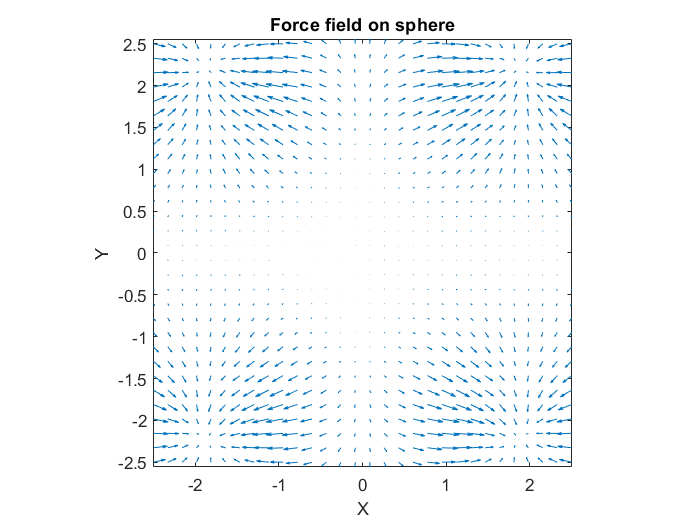

x = linspace(-2.5, 2.5, 30);
y = x;
[xx, yy] = meshgrid(x, y);
xyz = [xx(:), yy(:), 0*xx(:)].';
fxyz = ott.forcetorque(beam, sphere, 'position', xyz);

figure();
quiver(xx, yy, reshape(fxyz(1, :), size(xx)), reshape(fxyz(2, :), size(xx)));
axis image;
xlabel('X');
ylabel('Y');
title('Force field on sphere');